# Actividad 1.9 (Landmarks)

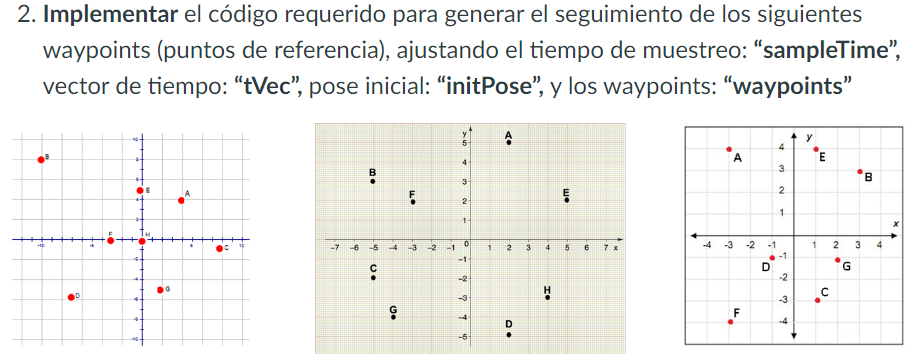

Para este segundo punto, genere el seguimiento de los waypoints para tres incisos, primero obtuve los puntos de referencia y luego de manera heuristica obtuve el tiempo de simulacion aproximado para concluir con toda la trayectoria. En estos ejercicios utilice una velocidad linal de 1 y angular de 1.5, por lo que se puede observar en las graficas como al cambiar al siguiente waypoint y si hay un giro pronunciado, da una vuelta que se desvia mucho de la trayectoria, pero esto es debido a que la velocidad angular no es la suficiente con respecto a la lineal, en este caso la angular debe ser mucho mas grande que la lineal, para que la vuelta sea muy rapida y no avance tanto al mismo tiempo.

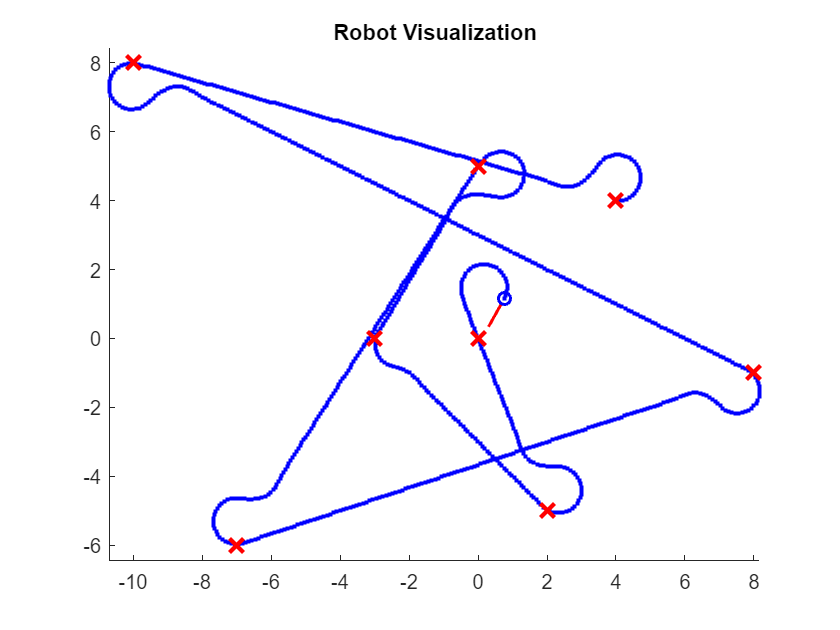

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:98;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4; -10,8; 8,-1; -7,-6; 0,5; -3,0; 2,-5; 0,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

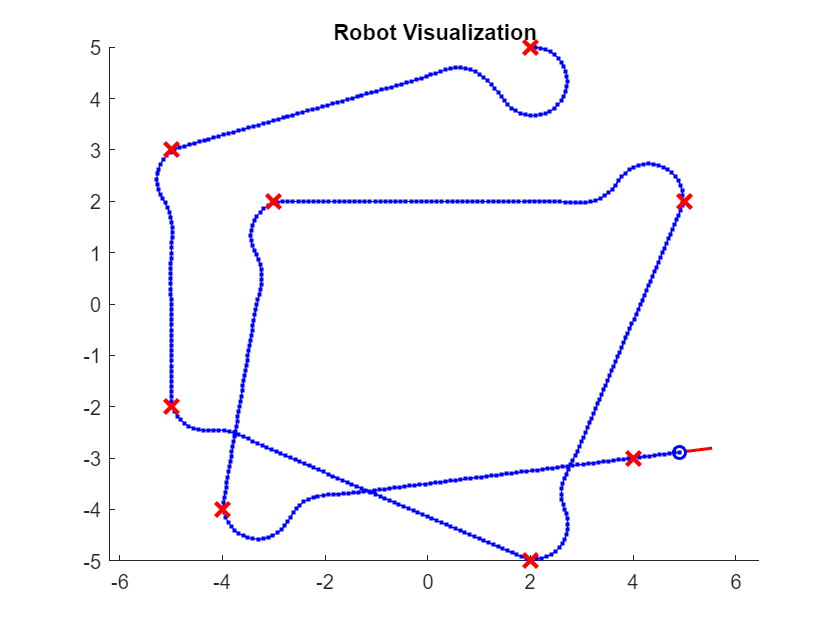


%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:55;         % Time array

initPose = [2;5;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,-4; 4,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

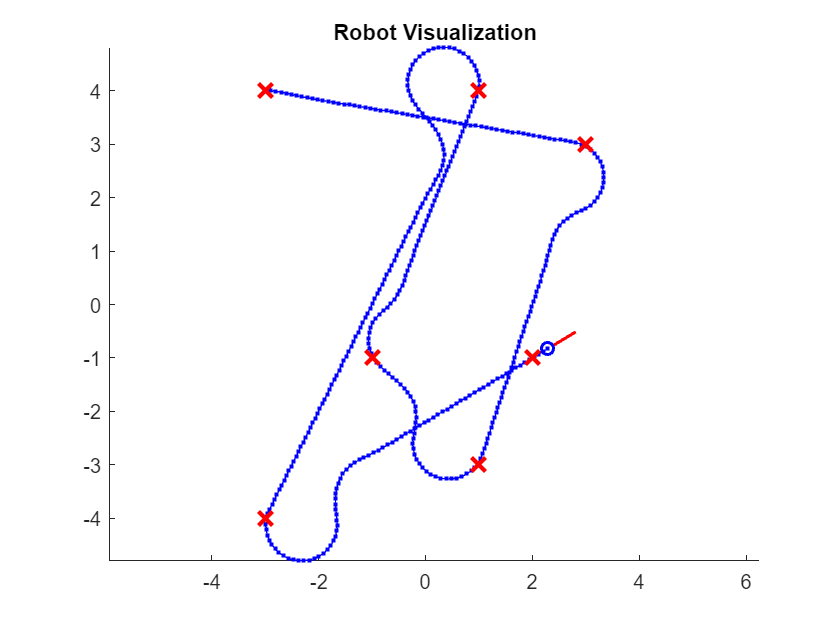

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:41;         % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

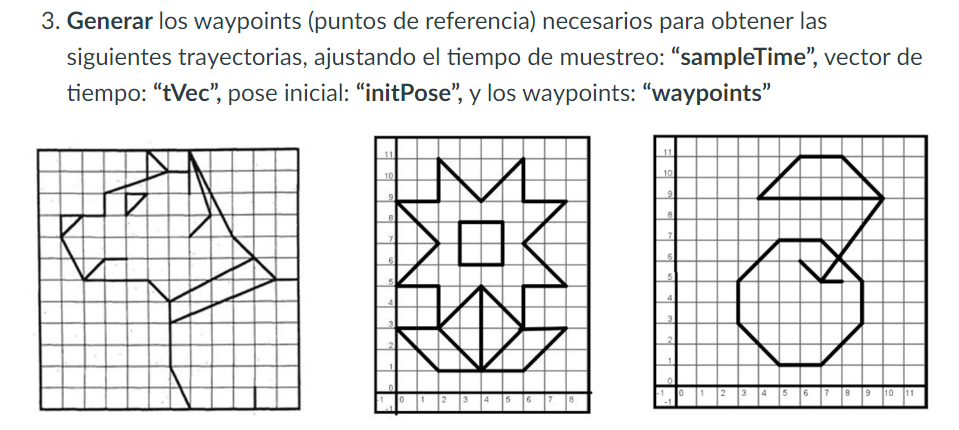

Para este tercer punto, genere los waypoints para obtener las tres trayectorias de este punto. Como en el punto anterior, el vector de tiempo se obtuve de manera heursitica, pero a diferencia del punto anterior, use una velocidad lineal de 1 y una angular de 12, retomando lo mencionado anteriormente, la velocidad angular es mucho mayor a la lineal y se desvia menos de la trayectoria, y a pesar de que se aumento considerablemente la velocidad angular siguen estando esas curvas que se desvian un poco, pero esto es porque los waypoints son muy cercanos a diferencia de los ejercicios del punto anterior, entonces los giros deberían realizarse más rapido.

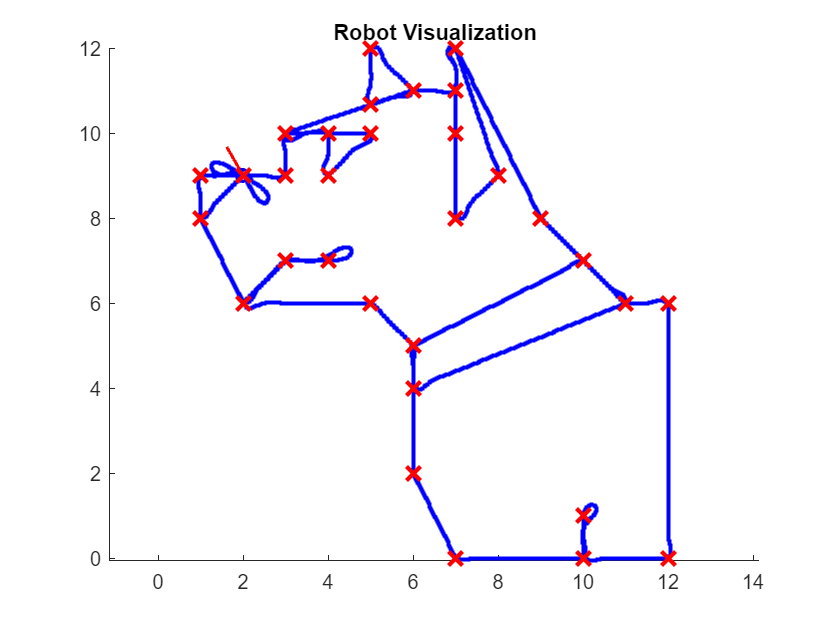

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:85;         % Time array

initPose = [1;8;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [1,8; 2,9; 1,9; 1,8; 2,6; 3,7; 4,7; 3,7; 2,6; 5,6; 6,5; 6,4; 
    11,6; 10,7; 6,5; 6,2; 7,0; 10,0; 10,1; 10,0; 12,0; 12,6; 11,6; 10,7; 
    9,8; 7,12; 7,10; 7,8; 8,9; 7,12; 7,11; 6,11; 5,10.66; 5,12; 6,11; 3,10;
    4,10; 5,10; 4,9; 4,10; 3,10; 3,9; 2,9];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 12;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

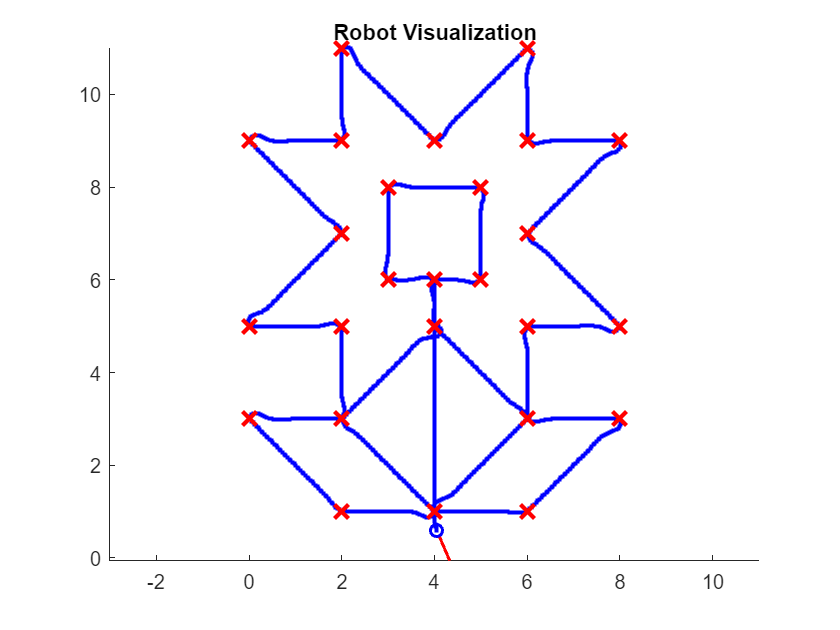

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:73;         % Time array

initPose = [4;5;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,5; 2,3; 4,1; 2,1; 0,3; 2,3; 2,5; 0,5; 2,7; 0,9; 2,9; 2,11; 
    4,9; 6,11; 6,9; 8,9; 6,7; 8,5; 6,5; 6,3; 8,3; 6,1; 4,1; 6,3; 4,5; 4,6; 
    3,6; 3,8; 5,8; 5,6; 4,6; 4,1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 12;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

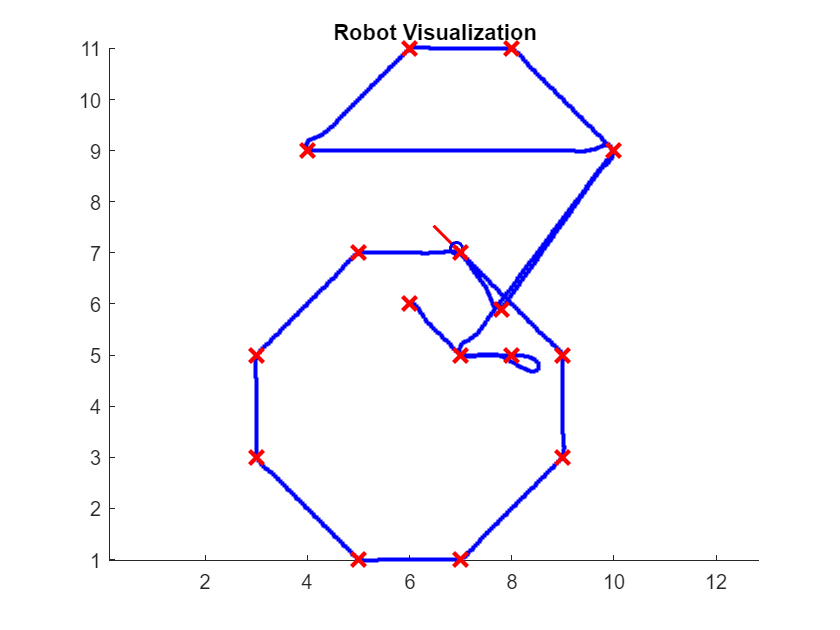


%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:48;         % Time array

initPose = [6;6;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [6,6; 7,5; 8,5; 7,5; 10,9; 4,9; 6,11; 8,11; 10,9; 7.8,5.9;
             7,7; 5,7; 3,5; 3,3; 5,1; 7,1; 9,3; 9,5; 7,7];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 12;

%% Simulation loop
%close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end